# P2. Dinámica Lateral del Vehículo

Sistemas de Control de Vehículos

Grado en Ingeniería Electrónica, Robótica y Mecátronica

Universidad de Málaga

Creado por: David Rodríguez Martínez

Última actualización: 28 Septiembre 2026

### Introducción y objetivos

Este archivo contiene a su vez el guión de la práctica y los bloques de código a completar. En esta práctica complementaremos el modelo de nuestro monoplaza que ya creamos en la P1, **incluyendo las componentes de la dinámica longitudinal y lateral**, y mantendremos las funciones de control longitudinal definidas en P1.

Para completar esta práctica se necesita conocer la ecuación de la dinámica lateral de un vehículo desarrollada en el Bloque 2 junto con el modelo de bicicleta cinemático y dinámico. 

Al terminar esta práctica deberás ser capaz de:

- Implementar el modelo de bicicleta cinemático (geométrico puro, sin deslizamiento) y el modelo dinámico (fuerzas de neumático con rigidez en deriva) para complementar el modelo longitudinal de P1 con un modelo que capture la dinámica lateral del vehículo. 

- Simular el evento 2 de la FS Driverless conocido como *skidpad*: giro estacionario, de forma simplificada.

- Adquirir datos de telemetría: velocidad de guiñada del vehículo, su aceleración lateral y los ángulos de deriva.

- Comparar los resultados de ambos modelos. 

#### Qué vas a implementar

A) El modelo cinématico (función `pasoCinematico`)

B) El modelo dinámico (función `pasoDinamico`)

### Parametros del vehículo y de la calzada

p = struct(); 

p.m    = 230;      % masa [kg]                              
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico                       
p.Af   = 1.1;      % área frontal [m^2]                        
p.fr  = 0.022;    % coef. de resistencia a la rodadura       
p.Fx_drive_max = 2500;   % fuerza motriz máxima [N]           
p.Fx_brake_max = 5000;   % fuerza de frenado máxima [N]       
p.theta = 0;      % inclinación de la calzada [rad]

% Define aquí los parámetros necesarios para describir la dinámica lateral
% del vehículo
p.ld = 0.765; % [m] distancia del CG al eje delantero en x
p.lt = 0.765; % [m] distancia del CG al eje trasero en x
p.lyd = 0.600; % [m] distancia del CG a las ruedas del eje delantero en y
p.lyt = 0.600; % [m] distancia del CG a las ruedas del eje trasero en y
p.hcg = 0.230; % [m] altura del centro de gravedad
% Coordenadas de cada rueda respecto al CG
% Orden: DI, DD, TI, TD
p.xw = [p.ld,p.ld,-p.lt,-p.lt];
p.L = p.ld+p.lt; 
p.yw = [p.lyd, -p.lyd, p.lyt, -p.lyt];
p.td = p.lyd + p.lyt;
p.tt = p.td; 
p.Iz = 130; % [kg m^2] inercia de guiñada
p.Cad = 35000; % [N/rad] rigidez deriva delantera
p.Cat = 50000; % [N/rad] rigidez deriva trasero --> vehículo subvirador! 
p.Caw = [p.Cad/2, p.Cad/2, p.Cat/2, p.Cat/2];
p.nCa = 0.8; 
p.mu_t = 1.5; % rozamiento neumático trasero
p.mu_d = 0.95*p.mu_t; % rozamiento neumático delantero
p.muw = [p.mu_d, p.mu_d, p.mu_t, p.mu_t];
% Perdida de adherencia lateral por exceso de traccion
p.Kslip = 3; % Intensidad de perdida lateral en ruedas traseras
% Dinamica temporal de perdida y recuperacion lateral
p.tau_slip_loss = 0.03; % Tiempo de perdida [s]
p.tau_slip_rec  = 0.50; % Tiempo de recuperacion [s]
% Reparto de fuerzas
p.Fzd0 = p.m*p.g*p.lt/p.L; % [N] Reparto de fuerzas inicial eje delantero
p.Fzt0 = p.m*p.g*p.ld/p.L; % [N] Reparto de fuerzas inicial eje trasero
p.Fzw0 = [p.Fzd0/2, p.Fzd0/2, p.Fzt0/2, p.Fzt0/2]; % [N] Reparto de fuerzas inicial rueda por rueda
p.drive_w = [0, 0, 0.5, 0.5]; % Reparto de tracción longitudinal en aceleración
p.brake_w = [0.3, 0.3, 0.2, 0.2]; % Reparto de tracción longitudinal en frenada
p.kRoll = 0.5; % fraccion del momento de balanceo soportada delante (Cambiar haciendo modelo de suspensión)


### Modelo del vehículo

Aquí se debe definir la física del movimiento del vehículo en sentido longitudinal y **lateral**. 

🚧 **Importante**: *En esta práctica definiremos el modelo completo que podrás usar como base para tu proyecto individual.*

Dado el **estado actual del vehículo, fuerza tractiva aplicada, y el ángulo de giro del volante** deberemos calcular dónde se encuentra el vehículo en el siguiente paso temporal:

💣 **OJO!:  **Será necesario compilar primero la geometría del circuito y el controlador. 

% Integración de la dinámica longitudinal y lateral

% u: variable de control = [Fx; delta] 
% z: vector de estados del vehículo [X; Y; psi; vx; vy; r]
% X, Y = posicion del CG global
% psi = rumbo, ángulo de guiñada
% vx, vy = velocidades en eje del chasis
% r = velocidad de guiñada

z0 = [0; -geom.R; 0; ctrl.v_skid; 0; 0]; % estado inicial del monoplaza

function z_next = pasoCinematico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    L = p.ld + p.lt;

    % Dinámica longitudinal (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    ax = (Fx - Ra - sign(vx)*Rr - Rg)/p.m; % ecuación del movimiento longitudinal
    vx_next = max(vx + ax*dt,0);

    %% Dinámica lateral [cinemático]
    beta = atan((p.lt/L)*tan(delta)); % ángulo de deriva cinemática
    r = (vx/p.lt)*tan(beta);
    vy = vx*tan(beta);

    % cambio al sistema global
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy; r]; % vector de estados en el siguiente paso temporal

end

function [z_next, tele] = pasoDinamico(z, u, p, dt, ax_prev, ay_prev, eta_prev)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    vy = z(5);
    r = z(6);
    L = p.ld + p.lt;
    xw = p.xw;
    yw = p.yw;


    % vx_c = max(vx, 1.0); % velocidad corregida para no dividir por 0,
    % desactivada ahora que el modelo usa atan2

    % Velocidades locales de las cuatro ruedas
    vxw = vx - r.*yw;
    vyw = vy + r.*xw;

    % ángulos de deriva y fuerzas laterales por rueda
    delta_w = [delta, delta, 0, 0];
    alpha_w = delta_w - atan2(vyw,vxw);
    

    %% Definimos límites de adherencia
    % Transferencia longitudinal entre ejes
    dFzx = p.m*ax_prev*p.hcg/p.L;

    % Transferencia lateral dentro de cada eje
    dFzyd = p.kRoll*p.m*ay_prev*p.hcg/p.td;
    dFzyt = (1-p.kRoll)*p.m*ay_prev*p.hcg/p.tt;

    % Orden: DI, DD, TI, TD
    Fzw = p.Fzw0 + [-dFzx/2, -dFzx/2, dFzx/2, dFzx/2] + [-dFzyd,    dFzyd, -dFzyt,   dFzyt];
    % Agarre longitudinal
    % Fuerzas laterales por rueda
    Caw = p.Caw .* (Fzw ./ p.Fzw0).^p.nCa;
    Fyw = Caw .* alpha_w;

    % Reparto longitudinal de tracción por rueda
    if Fx >= 0
        Fxw = Fx .* p.drive_w;
    else
        Fxw = Fx .* p.brake_w;
    end

    % Círculo de límite de adherencia rueda por rueda
    Fmax_w = p.muw .* Fzw; % Capacidad máxima de fuerza por rueda
    Fxw_sol = Fxw;
    Fres_w = hypot(Fxw,Fyw); % Módulo de la fuerza resultante solicitada
    lambda_w = min(ones(1,4),Fmax_w ./ max(Fres_w,eps)); % Factor de saturación

    %Fuerzas efectivas
    Fxw = lambda_w .* Fxw;
    Fyw = lambda_w .* Fyw;

    
    %% Perdida y recuperacion progresiva de adherencia lateral

    % Exceso de demanda longitudinal respecto a la adherencia
    s_w = max(0, abs(Fxw_sol) ./ max(Fmax_w,eps) - 1);

    % Factor objetivo de capacidad lateral
    eta_obj = ones(1,4);

    % Solo se provoca perdida adicional durante la traccion
    if Fx > 0
        eta_obj(3:4) = 1 ./ (1 + p.Kslip .* s_w(3:4));
    end

    % Estado de adherencia heredado del paso anterior
    eta_slip = eta_prev;

    % Actualizacion temporal de las ruedas traseras
    for i = 3:4

        % Perdida rapida o recuperacion lenta
        if eta_obj(i) < eta_prev(i)
            tau = p.tau_slip_loss;
        else
            tau = p.tau_slip_rec;
        end

        % Integracion exponencial estable
        factor = 1 - exp(-dt/tau);

        eta_slip(i) = eta_prev(i) + factor * (eta_obj(i) - eta_prev(i));

    end

    % Limitar el factor al intervalo fisicamente definido
    eta_slip = max(0,min(1,eta_slip));

    % Reduccion de la fuerza lateral trasera
    Fyw(3:4) = eta_slip(3:4) .* Fyw(3:4);

    % Componentes de las fuerzas laterales en el chasis
    Fxw_chasis = Fxw .* cos(delta_w) - Fyw .* sin(delta_w);

    Fyw_chasis = Fxw .* sin(delta_w) + Fyw .* cos(delta_w);

    % Fuerzas y momento resultantes
    SumFx = sum(Fxw_chasis); % Fuerza longitudinal total
    SumFy = sum(Fyw_chasis); % Fuerza lateral total
    SumMz = sum(p.xw .* Fyw_chasis - p.yw .* Fxw_chasis); % Momento de guiñada respecto al CG

    % Telemetria: datos del paso actual, sin modificar las fuerzas ni la dinamica
    tele.alpha_w = alpha_w;
    tele.Fxw = Fxw;
    tele.Fyw = Fyw;
    tele.Fzw = Fzw;
    tele.Mzw = p.xw .* Fyw_chasis - p.yw .* Fxw_chasis;
    tele.Mz_long = sum(p.xw .* (Fxw .* sin(delta_w)) - p.yw .* (Fxw .* cos(delta_w)));
    tele.Mz_lat = SumMz - tele.Mz_long;
    tele.lambda_w = lambda_w;
    tele.Fmax_w = Fmax_w;
    tele.s_w = s_w;
    tele.eta_slip = eta_slip;
    tele.eta_obj = eta_obj;

    % Dinámica longitudinal (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    
    % ecuaciones del movimiento 
    ax_fis = (SumFx - Ra - sign(vx)*Rr - Rg)/p.m;
    ay_fis = SumFy/p.m;
    ax  = ax_fis + vy*r; % ojo no olvidar el acoplamiento de la centripeta 
    ay = ay_fis - vx*r; 
    dr = SumMz/p.Iz;   
    tele.ax = ax_fis;
    tele.ay = ay_fis;

    vx_next = max(vx + ax*dt,0);
    vy_next = vy + ay*dt; 
    r_next = r + dr*dt;
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next]; 
end


### Controlador velocidad 

% Controlador PI de velocidad con saturación de fuerza identico a P1
ctrl.v_skid = 14; %[m/s] 5 originalmente 18 km/h , ahora 8 para probar diferencia
ctrl.Kp = 800; 
ctrl.Ki = 200;

function [Fx, e_int] = controlLongitudinal(v_ref, vx, e_int, dt, ctrl, p)
    e = v_ref - vx;
    e_int = e_int + e*dt;

    Fx = ctrl.Kp*e + ctrl.Ki*e_int; % PI
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max); % saturación para el cinemático
end


### Geometría del circuito de pruebas

Vamos a simular la prueba del skidpad simplificada, que consistirá en completar 2.5 vueltas a una trayectoría circular de radio constante interior de 15.25 m a través de un carril de 3 m de ancho. El objetivo será completar esta trayectoria en el menor tiempo posible sin salirse del carril. **Únicamente la 2ª vuelta es cronometrada**.  

%% SIMULADOR DE LA PRUEBA DEL SKIDPAD [NO MODIFICAR]
geom.R_in = 15.25/2; % radio interior (conos azules) [m]
geom.R_out = geom.R_in + 3; % radio exterior (conos amarillos; carril de 3m) [m]
geom.R = (geom.R_in + geom.R_out)/2; % radio de la línea central [m]

function hist = simularE2(z0, p, ctrl, geom, dt, Tmax, modelo)
    N = round(Tmax/dt);  z = z0;  e_int = 0;
    ax_prev = 0;
    ay_prev = 0;
    eta_prev = ones(1,4);
    L = p.ld + p.lt;
    delta = atan(L/geom.R); 
    hist.t=zeros(1,N); hist.X=zeros(1,N); hist.Y=zeros(1,N); hist.psi=zeros(1,N);
    hist.vx=zeros(1,N); hist.vy=zeros(1,N); hist.r=zeros(1,N);
    hist.af=zeros(1,N); hist.ar=zeros(1,N);
    % Telemetria nueva, solo para el modelo dinamico de cuatro ruedas
    es4R = strcmp(func2str(modelo), 'pasoDinamico');
    if es4R
        hist.alpha_w = zeros(N,4);
        hist.Fxw = zeros(N,4);
        hist.Fyw = zeros(N,4);
        hist.Fzw = zeros(N,4);
        hist.Mzw = zeros(N,4);
        hist.Mz_long = zeros(1,N);
        hist.Mz_lat = zeros(1,N);
        hist.lambda_w = zeros(N,4);
        hist.Fmax_w = zeros(N,4);
        hist.s_w = zeros(N,4);
        hist.eta_slip = ones(N,4);
    end
    for k = 1:N
        [Fx, e_int] = controlLongitudinal(ctrl.v_skid, z(4), e_int, dt, ctrl, p);
        u = [Fx; delta];
        vx_c = max(z(4), 1.0);
        hist.af(k) = delta - (z(5) + p.ld*z(6))/vx_c;
        hist.ar(k) =       - (z(5) - p.lt*z(6))/vx_c;
        if es4R
            [z, tele] = modelo(z, u, p, dt, ax_prev, ay_prev, eta_prev);
            hist.alpha_w(k,:) = tele.alpha_w;
            hist.Fxw(k,:) = tele.Fxw;
            hist.Fyw(k,:) = tele.Fyw;
            hist.Fzw(k,:) = tele.Fzw;
            hist.Mzw(k,:) = tele.Mzw;
            hist.Mz_long(k) = tele.Mz_long;
            hist.Mz_lat(k) = tele.Mz_lat;
            hist.lambda_w(k,:) = tele.lambda_w;
            hist.Fmax_w(k,:) = tele.Fmax_w;
            hist.s_w(k,:) = tele.s_w;
            hist.eta_slip(k,:) = tele.eta_slip;
            eta_prev = tele.eta_slip;
            ax_prev = tele.ax;
            ay_prev = tele.ay;

        else
            z = modelo(z, u, p, dt);
        end
        hist.t(k)=(k-1)*dt; hist.X(k)=z(1); hist.Y(k)=z(2); hist.psi(k)=z(3);
        hist.vx(k)=z(4); hist.vy(k)=z(5); hist.r(k)=z(6);
    end
    th = unwrap(atan2(hist.Y, hist.X));
    nV = floor((th - th(1))/(2*pi));                  
    hist.tVueltas = zeros(1, max(0, max(nV)));        
    for n = 1:numel(hist.tVueltas)
        hist.tVueltas(n) = hist.t(find(nV >= n, 1));
    end
    rad = hypot(hist.X, hist.Y);
    hist.fueraCarril = any(rad < geom.R_in | rad > geom.R_out);
end

function informarVueltas(nombre, hist)
    dur = diff([0, hist.tVueltas]);
    if numel(dur) >= 2
        fprintf('   %s: 2ª vuelta = %.2f s', nombre, dur(2));
    else
        fprintf('   %s: no completa 2 vueltas en Tmax', nombre);
    end
    if hist.fueraCarril, fprintf('   (¡sale del carril!)'); end
    fprintf('\n');
end

### Simulación

dt   = 0.002; 
Tmax = 2.5*2*pi*geom.R/ctrl.v_skid; % ~2.5 vueltas (la 2ª es la cronometrada)

histCin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoCinematico);
histDin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoDinamico);

idx = round(2*numel(histCin.t)/3):numel(histCin.t);
Rcin = mean(histCin.vx(idx)./max(histCin.r(idx),1e-6));
Rdin = mean(histDin.vx(idx)./max(histDin.r(idx),1e-6));

### Resultados 

Deberíamos observar como el monoplaza que sigue el modelo cinemático traza un cículo de radio ~9m (geometría pura) mientras que el modelo dinámico traza un radio ligeramente mayor debido al subviraje (ligero subviraje debido a angulos de deriva pequeños; determinados por la rigidez de deriva de ambos ejes). 

fprintf('Ackermann R = %.2f m  (delta = %.2f deg)\n', geom.R, atan((p.ld+p.lt)/geom.R)*180/pi);

Ackermann R = 9.12 m  (delta = 9.52 deg)


fprintf('Radio medido — cinemático: %.2f m | dinámico: %.2f m\n', Rcin, Rdin);

Radio medido — cinemático: 9.13 m | dinámico: 14.23 m


fprintf('Subviraje: el dinámico traza %.1f%% más radio.\n', 100*(Rdin-Rcin)/Rcin);

Subviraje: el dinámico traza 55.9% más radio.


fprintf('Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):\n');

Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):


informarVueltas('cinemático', histCin);

   cinemático: 2ª vuelta = 4.11 s


informarVueltas('dinámico  ', histDin);

   dinámico  : no completa 2 vueltas en Tmax   (¡sale del carril!)


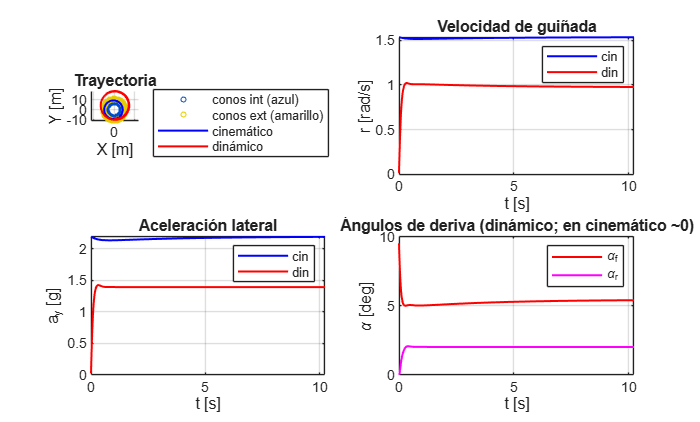

figure('Name','L2 · Skidpad','Color','w');

subplot(2,2,1); hold on; axis equal; grid on;  
  th = linspace(0,2*pi,200);
  plot(geom.R_in*cos(th), geom.R_in*sin(th), 'o','Color',[0 .3 .8],'MarkerSize',3);
  plot(geom.R_out*cos(th),geom.R_out*sin(th),'o','Color',[.9 .8 0],'MarkerSize',3);
  plot(histCin.X, histCin.Y, 'b-','LineWidth',1.2);
  plot(histDin.X, histDin.Y, 'r-','LineWidth',1.2);
  legend('conos int (azul)','conos ext (amarillo)','cinemático','dinámico','Location','bestoutside');
  title('Trayectoria'); xlabel('X [m]'); ylabel('Y [m]');

subplot(2,2,2);   
  plot(histCin.t,histCin.r,'b', histDin.t,histDin.r,'r','LineWidth',1.2);
  ylabel('r [rad/s]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Velocidad de guiñada');

subplot(2,2,3);   
  plot(histCin.t, histCin.vx.*histCin.r/9.81,'b', ...
       histDin.t, histDin.vx.*histDin.r/9.81,'r','LineWidth',1.2);
  ylabel('a_y [g]'); xlabel('t [s]'); grid on; legend('cin','din');
  title('Aceleración lateral');

subplot(2,2,4);   
  plot(histDin.t, histDin.af*180/pi,'r', histDin.t, histDin.ar*180/pi,'m','LineWidth',1.2);
  ylabel('\alpha [deg]'); xlabel('t [s]'); grid on; legend('\alpha_f','\alpha_r');
  title('Ángulos de deriva (dinámico; en cinemático ~0)');

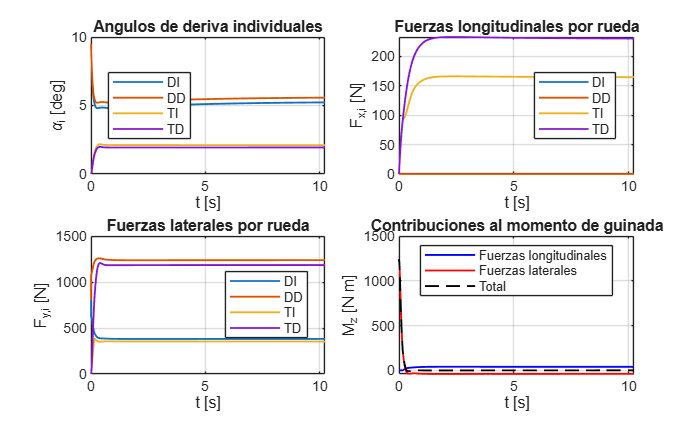


%% NUEVA FIGURA: telemetria del modelo dinamico de cuatro ruedas
% Orden de ruedas: DI, DD, TI, TD. No modifica la simulacion original.
figure('Name','Modelo 4 ruedas - Telemetria','Color','w');
nombres = {'DI','DD','TI','TD'};

subplot(2,2,1);
plot(histDin.t, rad2deg(histDin.alpha_w), 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('\alpha_i [deg]');
title('Angulos de deriva individuales'); legend(nombres,'Location','best');

subplot(2,2,2);
plot(histDin.t, histDin.Fxw, 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('F_{x,i} [N]');
title('Fuerzas longitudinales por rueda'); legend(nombres,'Location','best');

subplot(2,2,3);
plot(histDin.t, histDin.Fyw, 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('F_{y,i} [N]');
title('Fuerzas laterales por rueda'); legend(nombres,'Location','best');

subplot(2,2,4);
plot(histDin.t, histDin.Mz_long, 'b', ...
     histDin.t, histDin.Mz_lat, 'r', ...
     histDin.t, histDin.Mz_long + histDin.Mz_lat, 'k--', 'LineWidth',1.1);
grid on; xlabel('t [s]'); ylabel('M_z [N m]');
title('Contribuciones al momento de guinada');
legend('Fuerzas longitudinales','Fuerzas laterales','Total','Location','best');

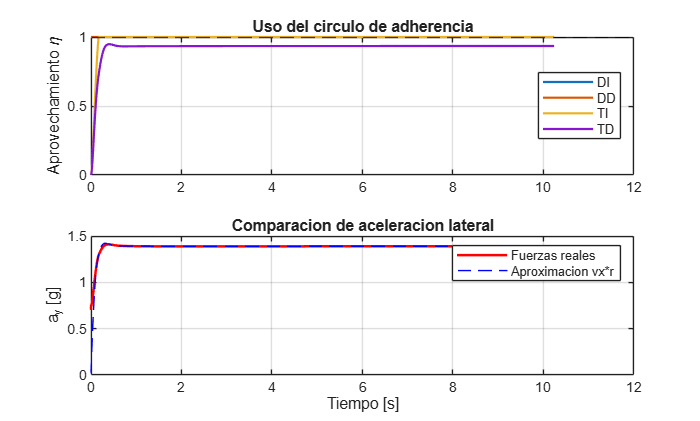

%% Comprobacion del circulo de adherencia

t = histDin.t(:);
Fx = histDin.Fxw;
Fy = histDin.Fyw;
Fz = histDin.Fzw;

% Aprovechamiento de adherencia por rueda
Fmax = Fz .* p.muw;
eta = hypot(Fx, Fy) ./ Fmax;

% Aceleracion lateral a partir de las fuerzas
delta = atan((p.ld + p.lt)/geom.R);
delta_w = [delta, delta, 0, 0];

Fy_chasis = Fx.*sin(delta_w) + Fy.*cos(delta_w);
ay_real = sum(Fy_chasis, 2)/(p.m*p.g);

% Graficas
figure('Color','w');

subplot(2,1,1)
plot(t, eta, 'LineWidth',1.3)
yline(1,'k--','Limite adherencia');
grid on;
ylabel('Aprovechamiento \eta');
legend('DI','DD','TI','TD','Location','best');
title('Uso del circulo de adherencia');

subplot(2,1,2)
plot(t, ay_real, 'r','LineWidth',1.5)
hold on;
plot(t, histDin.vx(:).*histDin.r(:)/p.g, 'b--');
grid on;
xlabel('Tiempo [s]');
ylabel('a_y [g]');
legend('Fuerzas reales','Aproximacion vx*r');
title('Comparacion de aceleracion lateral');


% Comprobacion numerica
fprintf('Aprovechamiento maximo por rueda:\n');

Aprovechamiento maximo por rueda:


disp(max(eta,[],1));

    1.0000    1.0000    1.0000    0.9482




fprintf('Aceleracion lateral maxima: %.3f g\n', ...
    max(abs(ay_real)));

Aceleracion lateral maxima: 1.409 g


fprintf('\n--- Resumen modelo 4 ruedas ---\n');


--- Resumen modelo 4 ruedas ---


fprintf('Velocidad final: %.2f m/s\n', histDin.vx(end));

Velocidad final: 13.95 m/s


fprintf('Guiñada final: %.3f rad/s\n', histDin.r(end));

Guiñada final: 0.977 rad/s


fprintf('Max |deriva| por rueda [deg]: ');

Max |deriva| por rueda [deg]: 

fprintf('%.2f ', max(abs(rad2deg(histDin.alpha_w)),[],1));

9.52 9.52 2.17 1.98 

fprintf('\nMax |Fx| por rueda [N]: ');


Max |Fx| por rueda [N]: 

fprintf('%.1f ', max(abs(histDin.Fxw),[],1));

0.0 0.0 165.6 232.3 

fprintf('\nMax |Fy| por rueda [N]: ');


Max |Fy| por rueda [N]: 

fprintf('%.1f ', max(abs(histDin.Fyw),[],1));

803.8 1258.1 386.8 1206.8 

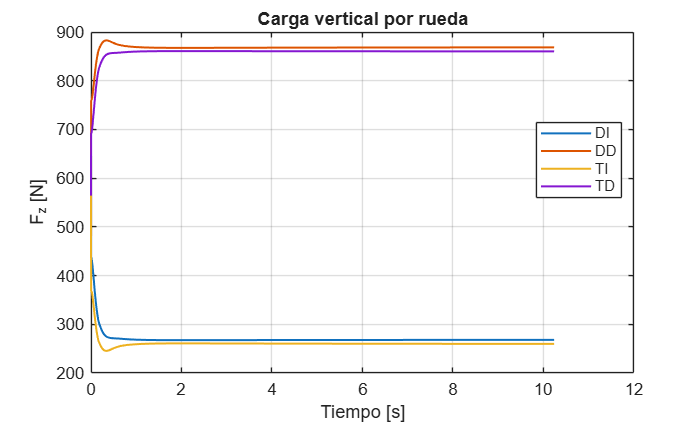

fprintf('\n');
%% Resultados: transferencia de carga y rigidez de deriva
t = histDin.t(:);
Fz = histDin.Fzw;
nombres = {'DI','DD','TI','TD'};

% Rigidez utilizada en cada paso
Ca = p.Caw .* (Fz ./ p.Fzw0).^p.nCa;

% Fuerzas efectivas y capacidad de adherencia
Fres = hypot(histDin.Fxw, histDin.Fyw);
Fmax = Fz .* p.muw;
eta = Fres ./ max(Fmax,eps);

figure
plot(t, Fz, 'LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('F_z [N]');
title('Carga vertical por rueda');
legend(nombres,'Location','best');

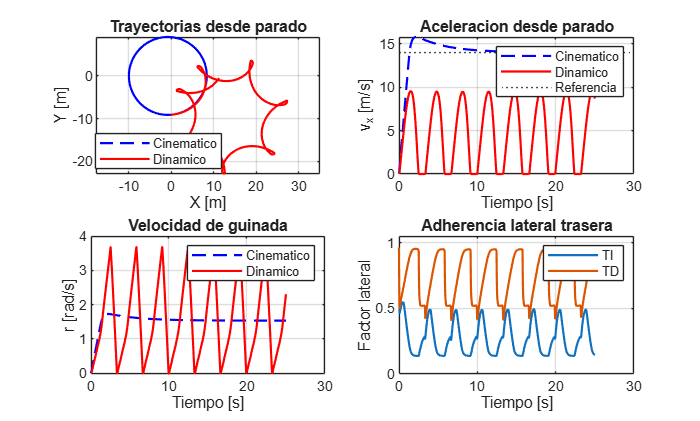


%% SKIDPAD DESDE PARADO

% Estado inicial con velocidad nula
z0Skid = [0; -geom.R; 0; 0; 0; 0];

% Duracion ampliada para incluir la aceleracion
TmaxSkid = 25;

% Ejecutamos ambos modelos con la misma referencia
histSkid0Cin = simularE2( ...
    z0Skid, p, ctrl, geom, dt, TmaxSkid, @pasoCinematico);

histSkid0Din = simularE2( ...
    z0Skid, p, ctrl, geom, dt, TmaxSkid, @pasoDinamico);

% Representacion de resultados
figure('Name','Skidpad desde parado','Color','w');

subplot(2,2,1)
plot(histSkid0Cin.X,histSkid0Cin.Y,'b--','LineWidth',1.3);
hold on;
plot(histSkid0Din.X,histSkid0Din.Y,'r','LineWidth',1.3);
axis equal; grid on;
xlabel('X [m]'); ylabel('Y [m]');
title('Trayectorias desde parado');
legend('Cinematico','Dinamico','Location','best');

subplot(2,2,2)
plot(histSkid0Cin.t,histSkid0Cin.vx,'b--', ...
    histSkid0Din.t,histSkid0Din.vx,'r','LineWidth',1.3);
yline(ctrl.v_skid,'k:');
grid on;
xlabel('Tiempo [s]'); ylabel('v_x [m/s]');
title('Aceleracion desde parado');
legend('Cinematico','Dinamico','Referencia');

subplot(2,2,3)
plot(histSkid0Cin.t,histSkid0Cin.r,'b--', ...
    histSkid0Din.t,histSkid0Din.r,'r','LineWidth',1.3);
grid on;
xlabel('Tiempo [s]'); ylabel('r [rad/s]');
title('Velocidad de guinada');
legend('Cinematico','Dinamico');

subplot(2,2,4)
plot(histSkid0Din.t,histSkid0Din.eta_slip(:,3:4),...
    'LineWidth',1.3);
grid on;
xlabel('Tiempo [s]');
ylabel('Factor lateral');
ylim([0 1.05]);
title('Adherencia lateral trasera');
legend('TI','TD');


fprintf('\n--- SKIDPAD DESDE PARADO ---\n');


--- SKIDPAD DESDE PARADO ---


fprintf('Reduccion lateral maxima: %.1f %%\n', ...
    100*(1-min(histSkid0Din.eta_slip(:,3:4),[],'all')));

Reduccion lateral maxima: 86.2 %


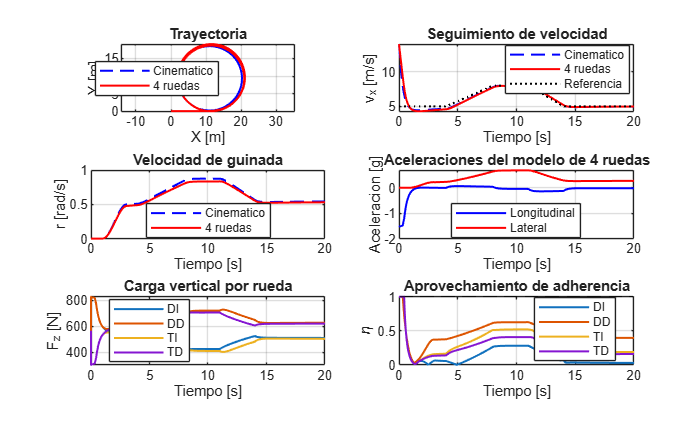

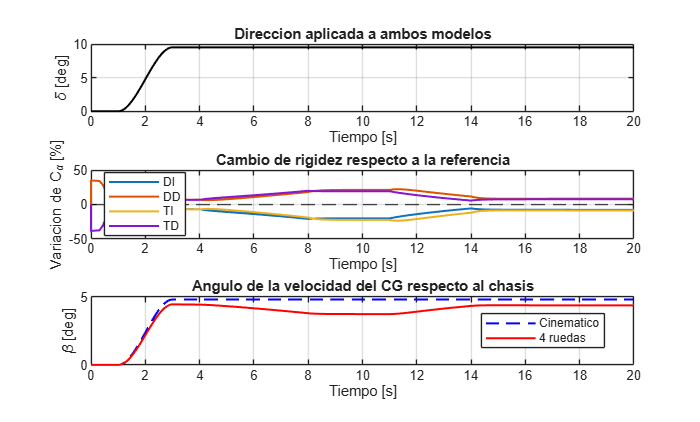


--- Curva: aceleracion y frenada ---
Carga minima por rueda [N]:
  419.1773  564.0750  302.3912  302.3912

Maximo aprovechamiento por rueda:
    1.0000    1.0000    1.0000    1.0000

Tiempo con alguna rueda saturada: 2.2 %
Error maximo de equilibrio vertical: 0.000e+00 N


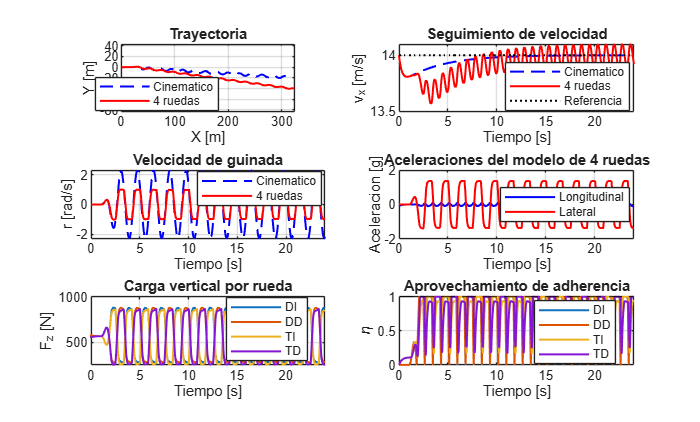

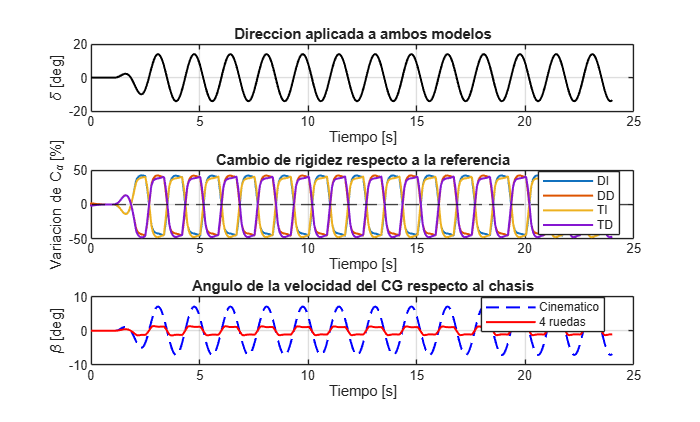


--- Eslalon ---
Carga minima por rueda [N]:
  261.1424  261.1669  249.3583  247.9065

Maximo aprovechamiento por rueda:
    1.0000    1.0000    1.0000    1.0000

Tiempo con alguna rueda saturada: 74.8 %
Error maximo de equilibrio vertical: 0.000e+00 N



%% Nuevos ensayos: curva con aceleracion/frenada y eslalon
dtEnsayo = 0.002;

% Caso 2: curva con aceleracion y frenada
caso2.nombre = 'Curva: aceleracion y frenada';
caso2.T = 20;
caso2.v0 = 14;

% Direccion equivalente al radio nominal del skidpad
caso2.delta = atan(p.L/9.125);

% Caso 4: eslalon
caso4.nombre = 'Eslalon';
caso4.T = 24;
caso4.v0 = 14;
caso4.amplitud = deg2rad(14);
caso4.frecuencia = 0.6; % Hz

casos = {caso2, caso4};

for j = 1:numel(casos)
    caso = casos{j};

    cin = simularManiobra(p, ctrl, dtEnsayo, caso, j, false);
    din = simularManiobra(p, ctrl, dtEnsayo, caso, j, true);

    mostrarManiobra(cin, din, p, caso.nombre);

    if j == 1
        histCurvaCin = cin;
        histCurvaDin = din;
    else
        histEslalonCin = cin;
        histEslalonDin = din;
    end
end

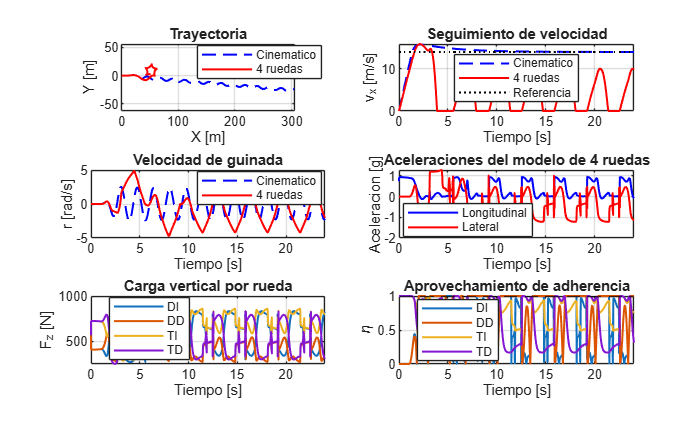

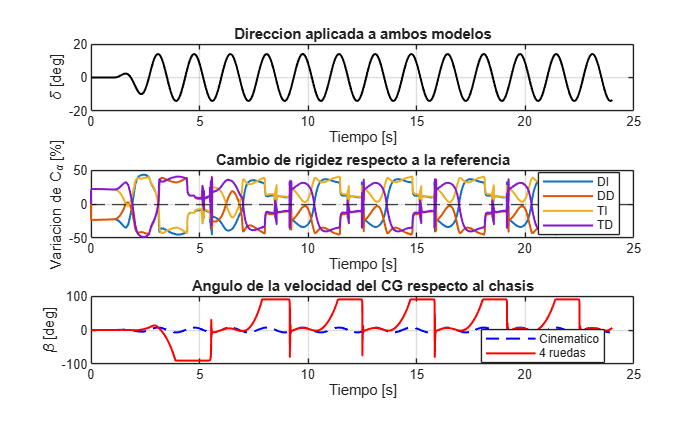


--- Eslalon desde parado ---
Carga minima por rueda [N]:
  266.9652  267.5469  279.6610  246.0380

Maximo aprovechamiento por rueda:
    1.0000    1.0000    1.0000    1.0000

Tiempo con alguna rueda saturada: 98.8 %
Error maximo de equilibrio vertical: 4.547e-13 N



%% ESLALON DESDE PARADO

% Nueva configuracion del eslalon
casoEslalon0 = caso4;

casoEslalon0.nombre = 'Eslalon desde parado';
casoEslalon0.v0 = 0;
casoEslalon0.vobjetivo = 14;
casoEslalon0.T = 24;

% Ejecutamos ambos modelos
histEslalon0Cin = simularManiobra( ...
    p, ctrl, dtEnsayo, casoEslalon0, 2, false);

histEslalon0Din = simularManiobra( ...
    p, ctrl, dtEnsayo, casoEslalon0, 2, true);

% Graficas originales de comparacion
mostrarManiobra( ...
    histEslalon0Cin, histEslalon0Din, ...
    p, casoEslalon0.nombre);

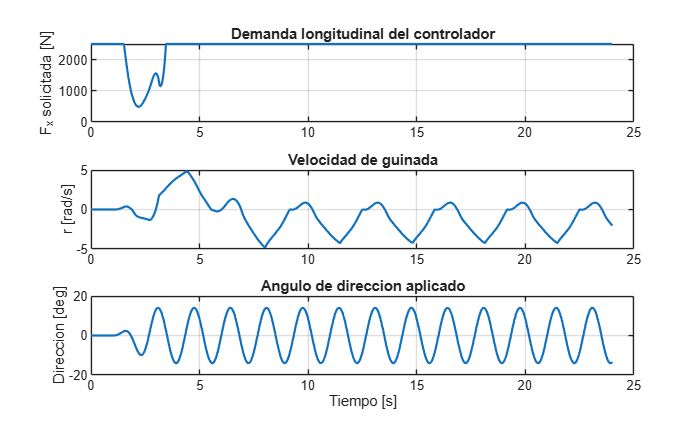


% Diagnostico adicional
figure('Name','Eslalon desde parado - Diagnostico',...
    'Color','w');

subplot(3,1,1)
plot(histEslalon0Din.t,histEslalon0Din.Fx_cmd,...
    'LineWidth',1.3);
grid on;
ylabel('F_x solicitada [N]');
title('Demanda longitudinal del controlador');

subplot(3,1,2)
plot(histEslalon0Din.t,histEslalon0Din.z(:,6),...
    'LineWidth',1.3);
grid on;
ylabel('r [rad/s]');
title('Velocidad de guinada');

subplot(3,1,3)
plot(histEslalon0Din.t, ...
    rad2deg(histEslalon0Din.delta), ...
    'LineWidth',1.3);
grid on;
xlabel('Tiempo [s]');
ylabel('Direccion [deg]');
title('Angulo de direccion aplicado');

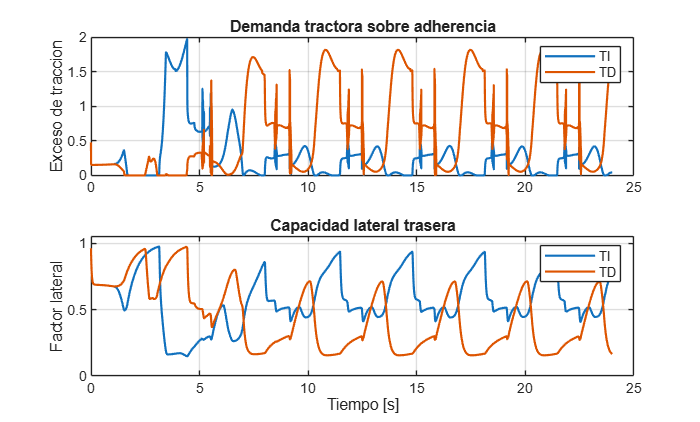




%% Perdida lateral del eslalon desde parado

figure('Name','Eslalon - Deslizamiento trasero','Color','w');

subplot(2,1,1)
plot(histEslalon0Din.t, ...
    histEslalon0Din.s_w(:,3:4), ...
    'LineWidth',1.3);
grid on;
ylabel('Exceso de traccion');
legend('TI','TD');
title('Demanda tractora sobre adherencia');

subplot(2,1,2)
plot(histEslalon0Din.t, ...
    histEslalon0Din.eta_slip(:,3:4), ...
    'LineWidth',1.3);
grid on;
xlabel('Tiempo [s]');
ylabel('Factor lateral');
ylim([0 1.05]);
legend('TI','TD');
title('Capacidad lateral trasera');


fprintf('\n--- ESLALON DESDE PARADO ---\n');


--- ESLALON DESDE PARADO ---


fprintf('Reduccion lateral maxima: %.1f %%\n', ...
    100*(1-min(histEslalon0Din.eta_slip(:,3:4),[],'all')));

Reduccion lateral maxima: 85.4 %



%% ENSAYO 4: Arranque desde parado con maxima traccion

% Configuracion
dtArr = 0.002;
TArr = 8;
NArr = round(TArr/dtArr);

FxArr = p.Fx_drive_max;  % Maxima demanda motriz: 2500 N
deltaArr = deg2rad(15); % Direccion constante

% Comparacion sin y con perdida lateral adicional
Kvalores = [0, 3];
nCasos = numel(Kvalores);

arranque = cell(1,nCasos);

for j = 1:nCasos

    pTest = p;
    pTest.Kslip = Kvalores(j);

    % Estado inicial: vehiculo parado
    z = [0; 0; 0; 0; 0; 0];

    ax_prev = 0;
    ay_prev = 0;
    eta_prev = ones(1,4);

    % Inicializacion de telemetria
    h.t = (0:NArr-1)'*dtArr;
    h.z = zeros(NArr,6);
    h.Fxw = zeros(NArr,4);
    h.Fyw = zeros(NArr,4);
    h.Fmax_w = zeros(NArr,4);
    h.s_w = zeros(NArr,4);
    h.eta_slip = ones(NArr,4);
    h.ax = zeros(NArr,1);
    h.ay = zeros(NArr,1);

    % Demanda constante, sin controlador PI
    u = [FxArr; deltaArr];

    for k = 1:NArr

        h.z(k,:) = z.';

        [z_next, tele] = pasoDinamico(z, u, pTest, dtArr, ax_prev, ay_prev, eta_prev);

        h.Fxw(k,:) = tele.Fxw;
        h.Fyw(k,:) = tele.Fyw;
        h.Fmax_w(k,:) = tele.Fmax_w;
        h.s_w(k,:) = tele.s_w;
        h.eta_slip(k,:) = tele.eta_slip;
        eta_prev = tele.eta_slip;
        h.ax(k) = tele.ax;
        h.ay(k) = tele.ay;

        ax_prev = tele.ax;
        ay_prev = tele.ay;

        z = z_next;
    end

    arranque{j} = h;
end

%% Comparacion de resultados

% Recuperar resultados de ambas simulaciones
h0 = arranque{1};  % Sin deslizamiento adicional
h3 = arranque{2};  % Con deslizamiento adicional

% Comprobar que se han almacenado los estados
disp(fieldnames(h0))

    {'t'       }
    {'z'       }
    {'vref'    }
    {'delta'   }
    {'Fx_cmd'  }
    {'Fzw'     }
    {'Caw'     }
    {'eta'     }
    {'ax'      }
    {'ay'      }
    {'lambda_w'}
    {'s_w'     }
    {'eta_slip'}
    {'Fxw'     }
    {'Fyw'     }
    {'Fmax_w'  }



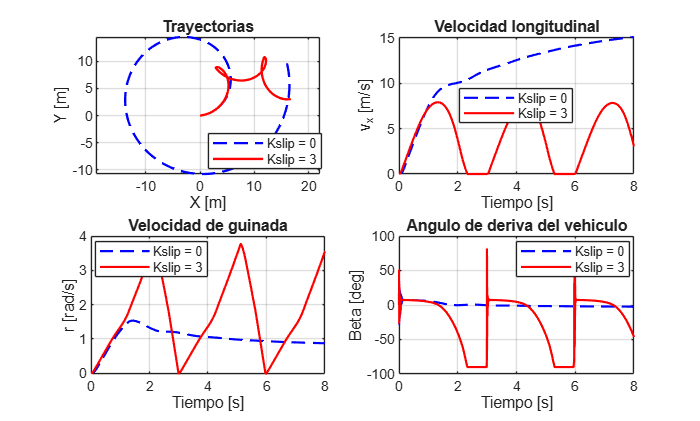


assert(isfield(h0,'z'), ...
    'No existe el campo z. Ejecuta primero el bucle del Ensayo 4.');

assert(isfield(h3,'z'), ...
    'No existe el campo z en la segunda simulacion.');


figure('Name','Ensayo 4 - Arranque con direccion',...
       'Color','w');

subplot(2,2,1)
plot(h0.z(:,1),h0.z(:,2),'b--','LineWidth',1.4);
hold on;
plot(h3.z(:,1),h3.z(:,2),'r','LineWidth',1.4);
axis equal; grid on;
xlabel('X [m]'); ylabel('Y [m]');
title('Trayectorias');
legend('Kslip = 0','Kslip = 3','Location','best');

subplot(2,2,2)
plot(h0.t,h0.z(:,4),'b--', ...
     h3.t,h3.z(:,4),'r','LineWidth',1.3);
grid on;
xlabel('Tiempo [s]'); ylabel('v_x [m/s]');
title('Velocidad longitudinal');
legend('Kslip = 0','Kslip = 3','Location','best');

subplot(2,2,3)
plot(h0.t,h0.z(:,6),'b--', ...
     h3.t,h3.z(:,6),'r','LineWidth',1.3);
grid on;
xlabel('Tiempo [s]'); ylabel('r [rad/s]');
title('Velocidad de guinada');
legend('Kslip = 0','Kslip = 3','Location','best');

subplot(2,2,4)
plot(h0.t,rad2deg(atan2(h0.z(:,5),h0.z(:,4))), ...
     'b--','LineWidth',1.3);
hold on;
plot(h3.t,rad2deg(atan2(h3.z(:,5),h3.z(:,4))), ...
     'r','LineWidth',1.3);
grid on;
xlabel('Tiempo [s]'); ylabel('Beta [deg]');
title('Angulo de deriva del vehiculo');
legend('Kslip = 0','Kslip = 3','Location','best');

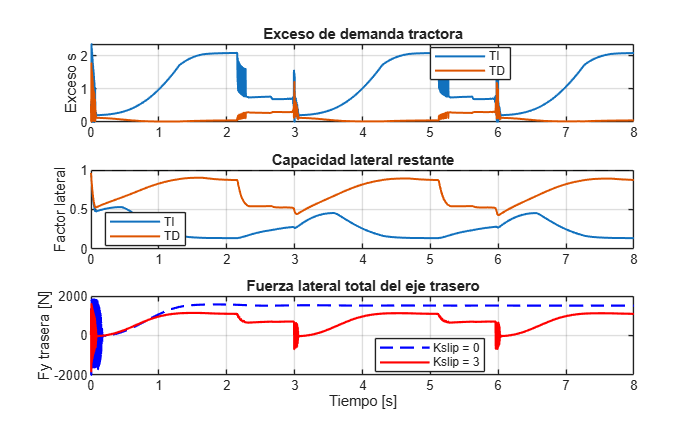


%% Diagnostico del mecanismo de perdida lateral

figure('Name','Ensayo 4 - Perdida de adherencia trasera',...
       'Color','w');

subplot(3,1,1)
plot(h3.t,h3.s_w(:,3:4),'LineWidth',1.2);
grid on;
ylabel('Exceso s');
title('Exceso de demanda tractora');
legend('TI','TD','Location','best');

subplot(3,1,2)
plot(h3.t,h3.eta_slip(:,3:4),'LineWidth',1.2);
hold on;
yline(1,'k--');
grid on;
ylabel('Factor lateral');
title('Capacidad lateral restante');
legend('TI','TD','Location','best');

subplot(3,1,3)
plot(h0.t,sum(h0.Fyw(:,3:4),2),'b--', ...
     h3.t,sum(h3.Fyw(:,3:4),2),'r', ...
     'LineWidth',1.3);
grid on;
xlabel('Tiempo [s]');
ylabel('Fy trasera [N]');
title('Fuerza lateral total del eje trasero');
legend('Kslip = 0','Kslip = 3','Location','best');


%% Resumen numerico

fprintf('\n--- ENSAYO 4: ARRANQUE CON DIRECCION ---\n');


--- ENSAYO 4: ARRANQUE CON DIRECCION ---



for j = 1:nCasos
    h = arranque{j};

    fprintf('\nKslip = %.1f\n',Kvalores(j));
    fprintf('Velocidad final: %.2f m/s\n',h.z(end,4));
    fprintf('Guiñada final: %.3f rad/s\n',h.z(end,6));

    beta = atan2(h.z(:,5),h.z(:,4));
    fprintf('Max |beta|: %.2f deg\n', ...
        max(abs(rad2deg(beta))));

    fprintf('Reduccion lateral maxima: %.1f %%\n', ...
        100*(1-min(h.eta_slip(:,3:4),[],'all')));

    fprintf('Tiempo con perdida lateral adicional: %.1f %%\n', ...
        100*mean(any(h.eta_slip(:,3:4)<1-1e-6,2)));
end


Kslip = 0.0


Velocidad final: 15.09 m/s


Guiñada final: 0.874 rad/s


Max |beta|: 50.59 deg


Reduccion lateral maxima: 0.0 %


Tiempo con perdida lateral adicional: 0.0 %



Kslip = 3.0


Velocidad final: 3.04 m/s


Guiñada final: 3.552 rad/s


Max |beta|: 90.00 deg


Reduccion lateral maxima: 86.2 %


Tiempo con perdida lateral adicional: 100.0 %


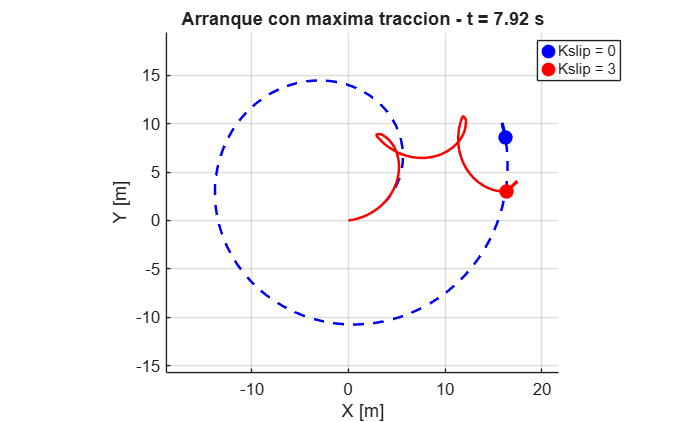



%% ANIMACION DEL ENSAYO 4

figure('Name','Animacion - Sobreviraje por potencia',...
    'Color','w');

hold on; grid on; axis equal;
xlabel('X [m]');
ylabel('Y [m]');
title('Arranque desde parado: Kslip = 0 frente a Kslip = 3');

% Limites comunes a ambas trayectorias
Xtotal = [h0.z(:,1); h3.z(:,1)];
Ytotal = [h0.z(:,2); h3.z(:,2)];

margen = 5;
xlim([min(Xtotal)-margen, max(Xtotal)+margen]);
ylim([min(Ytotal)-margen, max(Ytotal)+margen]);

% Trayectorias animadas
tray0 = animatedline('Color','b','LineStyle','--',...
    'LineWidth',1.5);
tray3 = animatedline('Color','r','LineWidth',1.5);

% Vehiculos: posicion y orientacion
veh0 = plot(NaN,NaN,'bo','MarkerFaceColor','b',...
    'MarkerSize',8);
veh3 = plot(NaN,NaN,'ro','MarkerFaceColor','r',...
    'MarkerSize',8);

dir0 = plot(NaN,NaN,'b-','LineWidth',2);
dir3 = plot(NaN,NaN,'r-','LineWidth',2);

legend([veh0,veh3],{'Kslip = 0','Kslip = 3'},...
    'Location','best');

Ldib = p.L;

% Mostrar aproximadamente 100 fotogramas
salto = max(1,round(NArr/100));

for k = 1:salto:NArr

    % Posiciones
    x0 = h0.z(k,1);
    y0 = h0.z(k,2);
    x3 = h3.z(k,1);
    y3 = h3.z(k,2);

    % Orientaciones
    psi0 = h0.z(k,3);
    psi3 = h3.z(k,3);

    addpoints(tray0,x0,y0);
    addpoints(tray3,x3,y3);

    set(veh0,'XData',x0,'YData',y0);
    set(veh3,'XData',x3,'YData',y3);

    % Flechas de orientacion del chasis
    set(dir0,'XData',[x0,x0+Ldib*cos(psi0)],...
        'YData',[y0,y0+Ldib*sin(psi0)]);

    set(dir3,'XData',[x3,x3+Ldib*cos(psi3)],...
        'YData',[y3,y3+Ldib*sin(psi3)]);

    title(sprintf('Arranque con maxima traccion - t = %.2f s', ...
        h0.t(k)));

    drawnow;
end

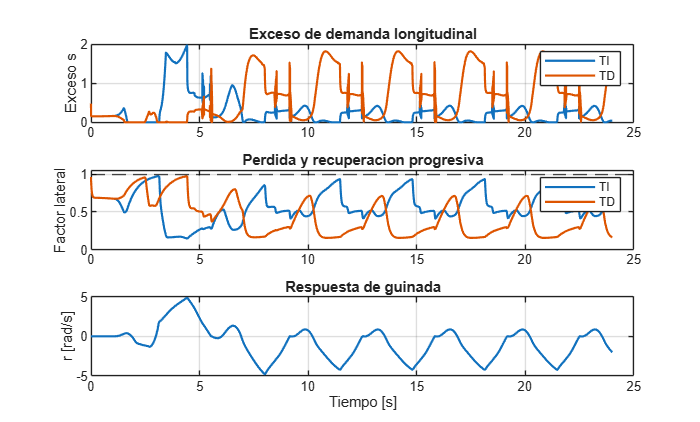


%% V6 - Evolucion temporal de la adherencia trasera

h = histEslalon0Din;

figure('Name','V6 - Recuperacion de adherencia','Color','w');

subplot(3,1,1)
plot(h.t,h.s_w(:,3:4),'LineWidth',1.3);
grid on;
ylabel('Exceso s');
title('Exceso de demanda longitudinal');
legend('TI','TD');

subplot(3,1,2)
plot(h.t,h.eta_slip(:,3:4),'LineWidth',1.3);
hold on;
yline(1,'k--');
grid on;
ylim([0 1.05]);
ylabel('Factor lateral');
title('Perdida y recuperacion progresiva');
legend('TI','TD');

subplot(3,1,3)
plot(h.t,h.z(:,6),'LineWidth',1.3);
grid on;
xlabel('Tiempo [s]');
ylabel('r [rad/s]');
title('Respuesta de guinada');


% Diagnostico de recuperacion
eta_min = min(h.eta_slip(:,3:4),[],2);

fprintf('\n--- V6: RECUPERACION DE ADHERENCIA ---\n');


--- V6: RECUPERACION DE ADHERENCIA ---


fprintf('Reduccion lateral maxima: %.1f %%\n', ...
    100*(1-min(eta_min)));

Reduccion lateral maxima: 85.4 %



fprintf('Tiempo con perdida lateral > 10%%: %.2f s\n', ...
    sum(eta_min < 0.9)*dtEnsayo);

Tiempo con perdida lateral > 10%: 23.90 s




function hist = simularManiobra(p, ctrl, dt, caso, tipo, dinamico)

N = round(caso.T/dt);
z = [0; 0; 0; caso.v0; 0; 0];

e_int = 0;
ax_prev = 0;
ay_prev = 0;
eta_prev = ones(1,4);

hist.t = (0:N-1)'*dt;
hist.z = zeros(N,6);
hist.vref = zeros(N,1);
hist.delta = zeros(N,1);
hist.Fx_cmd = zeros(N,1);

if dinamico
    hist.Fzw = zeros(N,4);
    hist.Caw = zeros(N,4);
    hist.eta = zeros(N,4);
    hist.ax = zeros(N,1);
    hist.ay = zeros(N,1);
    hist.lambda_w = zeros(N,4);
    hist.s_w = zeros(N,4);
    hist.eta_slip = ones(N,4);
end

for k = 1:N
    t = hist.t(k);

    if tipo == 1
        % Entrada en curva entre 1 y 3 s
        s = min(max((t-1)/2,0),1);
        entrada = s^2*(3-2*s);

        delta = caso.delta*entrada;

        % 0-4 s: 5 m/s
        % 4-8 s: subida progresiva hasta 8 m/s
        % 8-11 s: 8 m/s
        % 11-14 s: bajada progresiva hasta 5 m/s
        % 14-20 s: 5 m/s
        subida = min(max((t-4)/4,0),1);
        bajada = min(max((t-11)/3,0),1);

        vref = 5 + 3*subida - 3*bajada;

    else
        % Entrada suave al eslalon entre 1 y 3 s
        s = min(max((t-1)/2,0),1);
        entrada = s^2*(3-2*s);

        delta = entrada*caso.amplitud * sin(2*pi*caso.frecuencia*(t-1));

        
        % Velocidad de referencia independiente de la inicial
        if isfield(caso,'vobjetivo')
            vref = caso.vobjetivo;
        else
            vref = caso.v0;
        end

    end

    [Fx, e_int] = controlLongitudinal(vref, z(4), e_int, dt, ctrl, p);

    u = [Fx; delta];

    % Estados e inputs al inicio del paso
    hist.z(k,:) = z.';
    hist.vref(k) = vref;
    hist.delta(k) = delta;
    hist.Fx_cmd(k) = Fx;

    if dinamico
        [z_next, tele] = pasoDinamico(z, u, p, dt, ax_prev, ay_prev, eta_prev);

        hist.Fzw(k,:) = tele.Fzw;
        hist.Caw(k,:) = p.Caw.* (tele.Fzw./p.Fzw0).^p.nCa;

        hist.eta(k,:) = hypot(tele.Fxw,tele.Fyw)./ max(tele.Fmax_w,eps);

        hist.ax(k) = tele.ax;
        hist.ay(k) = tele.ay;
        hist.lambda_w(k,:) = tele.lambda_w;
        hist.s_w(k,:) = tele.s_w;
        hist.eta_slip(k,:) = tele.eta_slip;
        eta_prev = tele.eta_slip;

        ax_prev = tele.ax;
        ay_prev = tele.ay;

    else
        z_next = pasoCinematico(z, u, p, dt);
    end

    z = z_next;
end
end
function mostrarManiobra(cin, din, p, nombre)

t = din.t;
ruedas = {'DI','DD','TI','TD'};

figure('Name',nombre,'Color','w');

subplot(3,2,1)
plot(cin.z(:,1),cin.z(:,2),'b--', ...
    din.z(:,1),din.z(:,2),'r','LineWidth',1.2);
axis equal; grid on;
xlabel('X [m]'); ylabel('Y [m]');
title('Trayectoria');
legend('Cinematico','4 ruedas','Location','best');

subplot(3,2,2)
plot(t,cin.z(:,4),'b--', ...
    t,din.z(:,4),'r', ...
    t,din.vref,'k:','LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('v_x [m/s]');
title('Seguimiento de velocidad');
legend('Cinematico','4 ruedas','Referencia','Location','best');

subplot(3,2,3)
plot(t,cin.z(:,6),'b--', ...
    t,din.z(:,6),'r','LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('r [rad/s]');
title('Velocidad de guinada');
legend('Cinematico','4 ruedas','Location','best');

subplot(3,2,4)
plot(t,din.ax/p.g,'b', ...
    t,din.ay/p.g,'r','LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('Aceleracion [g]');
title('Aceleraciones del modelo de 4 ruedas');
legend('Longitudinal','Lateral','Location','best');

subplot(3,2,5)
plot(t,din.Fzw,'LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('F_z [N]');
title('Carga vertical por rueda');
legend(ruedas,'Location','best');

subplot(3,2,6)
plot(t,din.eta,'LineWidth',1.2);
yline(1,'k--','Limite');
grid on;
xlabel('Tiempo [s]'); ylabel('\eta');
title('Aprovechamiento de adherencia');
legend(ruedas,'Location','best');

% Segunda figura: entrada y respuesta de los neumaticos
figure('Name',[nombre ' - Direccion y rigidez'],'Color','w');

subplot(3,1,1)
plot(t,rad2deg(din.delta),'k','LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('\delta [deg]');
title('Direccion aplicada a ambos modelos');

subplot(3,1,2)
plot(t,100*(din.Caw./p.Caw - 1),'LineWidth',1.2);
yline(0,'k--');
grid on;
xlabel('Tiempo [s]'); ylabel('Variacion de C_\alpha [%]');
title('Cambio de rigidez respecto a la referencia');
legend(ruedas,'Location','best');

subplot(3,1,3)
betaCin = atan2(cin.z(:,5),cin.z(:,4));
betaDin = atan2(din.z(:,5),din.z(:,4));

plot(t,rad2deg(betaCin),'b--', t,rad2deg(betaDin),'r','LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('\beta [deg]');
title('Angulo de la velocidad del CG respecto al chasis');
legend('Cinematico','4 ruedas','Location','best');

fprintf('\n--- %s ---\n',nombre);
fprintf('Carga minima por rueda [N]:\n');
disp(min(din.Fzw,[],1));

fprintf('Maximo aprovechamiento por rueda:\n');
disp(max(din.eta,[],1));

fprintf('Tiempo con alguna rueda saturada: %.1f %%\n', 100*mean(any(din.lambda_w < 1-1e-6,2)));

fprintf('Error maximo de equilibrio vertical: %.3e N\n', max(abs(sum(din.Fzw,2)-p.m*p.g)));
end

Como vemos el modelo cinemático traza un círculo de radio constante al no tener deriva, mientras que el modelo dinámico traza un círculo ligeramente mayor con el mismo ángulo de giro del volante debido al subviraje del vehículo. Ambos experimentan una fuerza lateral de aproximadamente 0.55g. 

⚡ En Formula Student, el tiempo en el skidpad mide la aceleración lateral máxima del monoplaza. En la industria del automóvil, los ensayos de radio constante sirven además para medir el **gradiente de subviraje**.